# Face Detection and Tracking Using the KLT Algorithm

This example shows how to automatically detect and track a face using feature points. The approach in this example keeps track of the face even when the person tilts his or her head, or moves toward or away from the camera.

## Introduction

Object detection and tracking are important in many computer vision applications including activity recognition, automotive safety, and surveillance. In this example, you will develop a simple face tracking system by dividing the tracking problem into three parts: 

- Detect a face

- Identify facial features to track 

- Track the face

## Detect a Face

First, you must detect the face. Use the `vision.CascadeObjectDetector` object to detect the location of a face in a video frame. The cascade object detector uses the Viola-Jones detection algorithm and a trained classification model for detection. By default, the detector is configured to detect faces, but it can be used to detect other types of objects. 

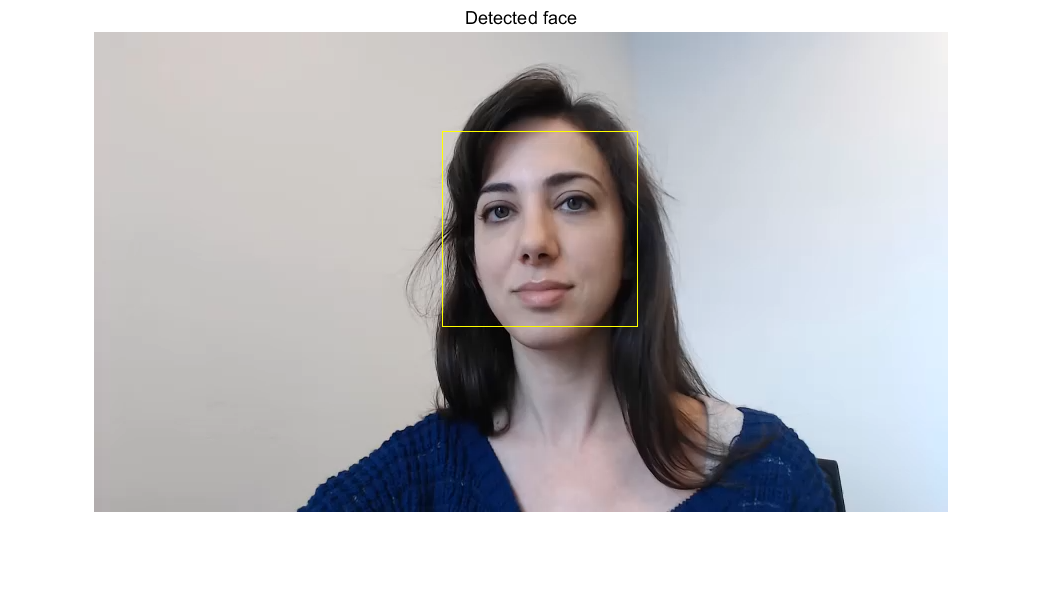

% Create a cascade detector object.
faceDetector = vision.CascadeObjectDetector();

% Read a video frame and run the face detector.
videoReader = VideoReader('face.mp4');
videoFrame      = readFrame(videoReader);
bbox            = step(faceDetector, videoFrame);

% Draw the returned bounding box around the detected face.
videoFrame = insertShape(videoFrame, 'Rectangle', bbox);
figure; imshow(videoFrame); title('Detected face');


% Convert the first box into a list of 4 points
% This is needed to be able to visualize the rotation of the object.
bboxPoints = bbox2points(bbox(1, :));

To track the face over time, this example uses the Kanade-Lucas-Tomasi (KLT) algorithm. While it is possible to use the cascade object detector on every frame, it is computationally expensive. It may also fail to detect the face, when the subject turns or tilts his head. This limitation comes from the type of trained classification model used for detection. The example detects the face only once, and then the KLT algorithm tracks the face across the video frames. 

## Identify Facial Features To Track

The KLT algorithm tracks a set of feature points across the video frames. Once the detection locates the face, the next step in the example identifies feature points that can be reliably tracked. This example uses the standard, "good features to track" proposed by Shi and Tomasi. 

Detect feature points in the face region.

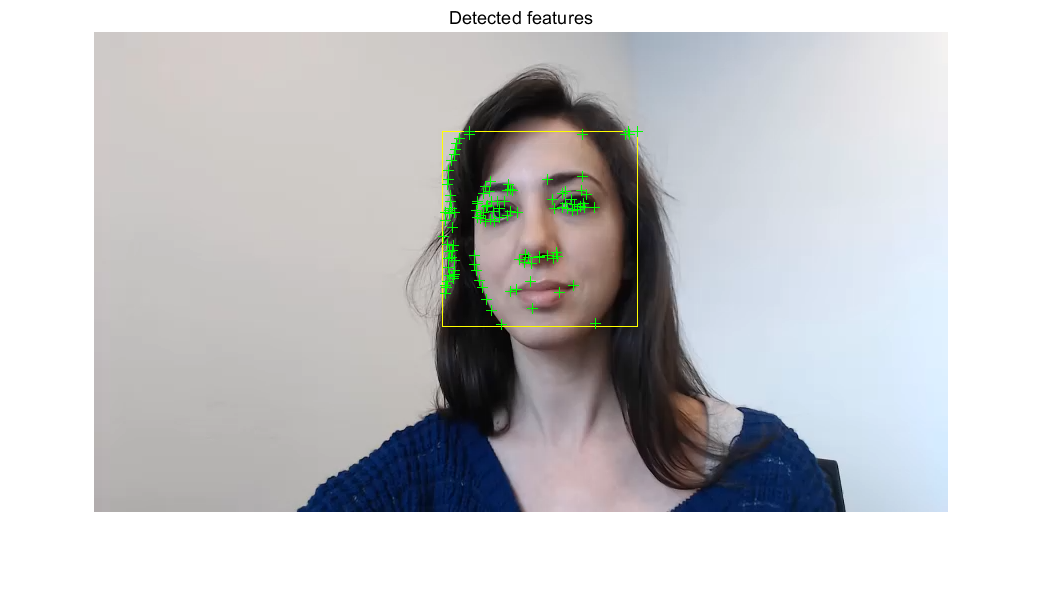

points = detectMinEigenFeatures(rgb2gray(videoFrame), 'ROI', bbox);

% Display the detected points.
figure, imshow(videoFrame), hold on, title('Detected features');
plot(points);

## Initialize a Tracker to Track the Points

With the feature points identified, you can now use the `vision.PointTracker` System object to track them. For each point in the previous frame, the point tracker attempts to find the corresponding point in the current frame. Then the `estimateGeometricTransform` function is used to estimate the translation, rotation, and scale between the old points and the new points. This transformation is applied to the bounding box around the face.

Create a point tracker and enable the bidirectional error constraint to make it more robust in the presence of noise and clutter.

pointTracker = vision.PointTracker('MaxBidirectionalError', 2);

% Initialize the tracker with the initial point locations and the initial
% video frame.
points = points.Location;
initialize(pointTracker, points, videoFrame);

## Initialize a Video Player to Display the Results

Create a video player object for displaying video frames.

videoPlayer  = vision.VideoPlayer('Position',...
    [100 100 [size(videoFrame, 2), size(videoFrame, 1)]+30]);

## Track the Face

Track the points from frame to frame, and use `estimateGeometricTransform` function to estimate the motion of the face.

Make a copy of the points to be used for computing the geometric transformation between the points in the previous and the current frames

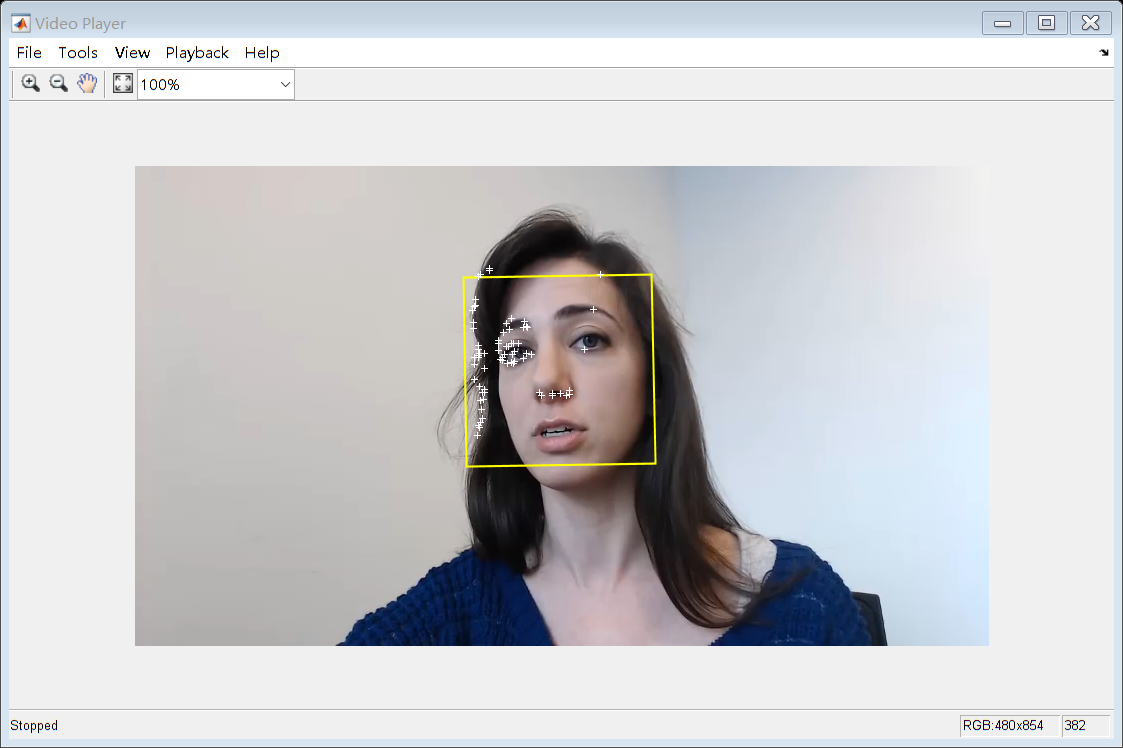

oldPoints = points;

while hasFrame(videoReader)
    % get the next frame
    videoFrame = readFrame(videoReader);

    % Track the points. Note that some points may be lost.
    [points, isFound] = step(pointTracker, videoFrame);
    visiblePoints = points(isFound, :);
    oldInliers = oldPoints(isFound, :);
    
    if size(visiblePoints, 1) >= 2 % need at least 2 points
        
        % Estimate the geometric transformation between the old points
        % and the new points and eliminate outliers
        [xform, oldInliers, visiblePoints] = estimateGeometricTransform(...
            oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
        
        % Apply the transformation to the bounding box points
        bboxPoints = transformPointsForward(xform, bboxPoints);
                
        % Insert a bounding box around the object being tracked
        bboxPolygon = reshape(bboxPoints', 1, []);
        videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, ...
            'LineWidth', 2);
                
        % Display tracked points
        videoFrame = insertMarker(videoFrame, visiblePoints, '+', ...
            'Color', 'white');       
        
        % Reset the points
        oldPoints = visiblePoints;
        setPoints(pointTracker, oldPoints);        
    end
    
    % Display the annotated video frame using the video player object
    step(videoPlayer, videoFrame);
end

% Clean up
release(videoPlayer);

release(pointTracker);

## Summary

In this example, you created a simple face tracking system that automatically detects and tracks a single face. Try changing the input video, and see if you are still able to detect and track a face. Make sure the person is facing the camera in the initial frame for the detection step.

## References

Viola, Paul A. and Jones, Michael J. "Rapid Object Detection using a Boosted Cascade of Simple Features", IEEE CVPR, 2001.

Bruce D. Lucas and Takeo Kanade. An Iterative Image Registration Technique with an Application to Stereo Vision. International Joint Conference on Artificial Intelligence, 1981.

Carlo Tomasi and Takeo Kanade. Detection and Tracking of Point Features. Carnegie Mellon University Technical Report CMU-CS-91-132, 1991.

Jianbo Shi and Carlo Tomasi. Good Features to Track. IEEE Conference on Computer Vision and Pattern Recognition, 1994.

Zdenek Kalal, Krystian Mikolajczyk and Jiri Matas. Forward-Backward Error: Automatic Detection of Tracking Failures. International Conference on Pattern Recognition, 2010

*Copyright 2014 The MathWorks, Inc.*